# Supervised Learning - Week 3 / Part 4

## Introduction

So far we've seen two major regression algorighms; linear regression and logistic regression for curve fitting tasks. In real world applications those algorithms might go through an issue which causes models perform poorly. In this part we will investigate one of those issues that our model can come across named "overfitting".

## What is Overfitting?

In order to understand the concept of overfitting let's take a look at some regression examples. Let's go back to our original problem of predicting housing prices using linear regression, where the aim is to predict the price of a property by using its size.

rng(11);
co = colororder;

% Synthetic house size vs. prices data
lim_house_size = [-5 5];
house_size = linspace(min(lim_house_size), max(lim_house_size), 51).';
house_price = house_size.^3 + house_size.^2 + 2*house_size + 3 + randn(size(house_size))*20;
disp(table(house_size, house_price))

    house_size    house_price
    __________    ___________

         -5         -115.45  
       -4.8         -129.64  
       -4.6         -83.828  
       -4.4         -47.724  
       -4.2         -64.311  
         -4         -53.612  
       -3.8         -93.629  
       -3.6         -39.025  
       -3.4         -18.513  
       -3.2          8.5791  
         -3         -3.1077  
       -2.8         -41.274  
       -2.6           20.45  
       -2.4          14.357  
       -2.2         -33.976  
         -2          4.8563  
       -1.8         -61.268  
       -1.6         -54.615  
       -1.4         -16.035  
       -1.2         -6.0321  
         -1          28.047  
       -0.8          19.195  
       -0.6          -4.139  
       -0.4         -5.0339  
       -0.2         -34.124  
          0         -11.994  
        0.2          21.261  
        0.4           10.03  
        0.6         -32.791  
 

Let's plot the price vs size data:

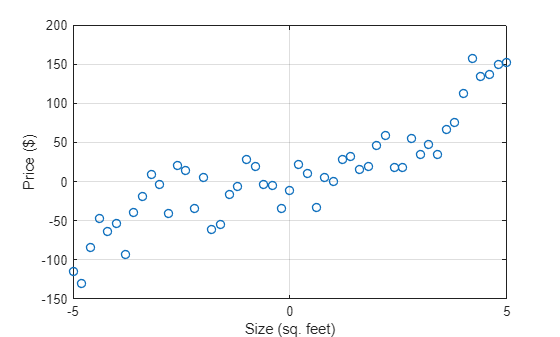

figure;
plot(house_size, house_price, 'o', 'LineWidth', 1)
xlabel('Size (sq. feet)')
ylabel('Price ($)')
grid on

### Linear Regression

#### Underfitting

We can fit a linear function $f_{w,b}(x) = w_1x + b $ to this data, where $w_1$and $b$ are the parameters that will be found from the data itself. The input parameter (size of a house) and corresponding price are denoted by $x$ and $f_{w,b}(x)$, respectively.

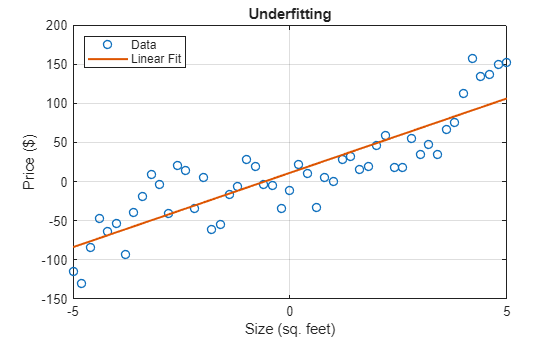

% Note that we will be using polyfit function to obtain underfit (1st
% degree), goodfit (3rd degree), and overfit (19th degree) models. Polyfit
% returns the coefficients as follows:
% [p,~,mu] = polyfit(x,y,n), performs centering and scaling to numerical
% properties of both polynomial and the fitting algorithm.
% The parameter p is the polynomial coefficients for the best fit, p(x) =
% p1*x^n + p2*x^(n-1) + ... + pn+1 The parameters mu(1) is the mean(x) and
% mu(2) is the std(x). Using these values, polyfit centers x at zero and
% scales it to have unit standard deviation.
load('polyfit_1.mat')
x1_val = (house_size-mu(1))./mu(2);
yval = (p(1).*x1_val) + p(2);

figure;
plot(house_size, house_price, 'o', 'LineWidth', 1)
hold on
plot(house_size, yval, '-', 'LineWidth', 1.5)
xlabel('Size (sq. feet)')
ylabel('Price ($)')
grid on
hold off
legend('Data', 'Linear Fit', 'Location','northwest')
title("Underfitting")

As we can see from the above fitting this is not a good model to represent the relationship between the size and the price of the houses in the dataset. 

It is clear from the data that as the size increases the rate of increase in the house price decreases up to a point and it increases again. Hence, we can say that this algorithm cannot fit the training data very well. The technical way of expressing this is that "**the model is underfitting the training data (or the algorithm has a high bias)**". A way to think about bias in machine learning is to imagine that the learning algorithm has a very strong preconception that housing prices will be a completely linear function of house size.

Let's look at another scenario that how the model could fit the data in the following subsection.

#### Good Fitting

Let's use a quadratic function $f(x) = w_1x + w_2x^2 + w_3x^3 +b $ to fit the data, where the $w_1$, $w_2$, and $b$ are the parameters to be found. Note that this cubic function has two input features $x$, $x^2$, and $x^3$.

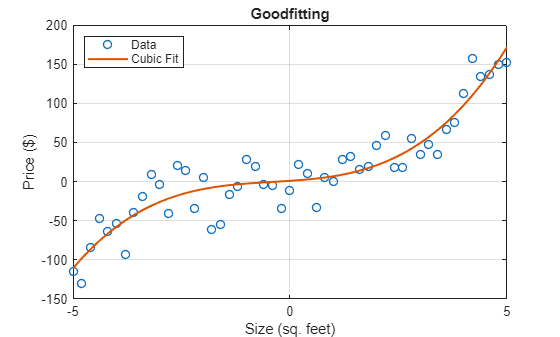

load('polyfit_3.mat')
x1_val = (house_size-mu(1))./mu(2);
yval = (p(1).*x1_val.^3) + (p(2).*x1_val.^2) + (p(3).*x1_val) + p(4);

figure;
plot(house_size, house_price, 'o', 'LineWidth', 1)
hold on
plot(house_size, yval, '-', 'LineWidth', 1.5)
xlabel('Size (sq. feet)')
ylabel('Price ($)')
grid on
hold off
legend('Data', 'Cubic Fit', 'Location','northwest')
title("Goodfitting")

From the above figure, we can see that our model fits the data (training set) pretty well. If you were to guess the price of a house not included in this training dataset, this model would probably perform well on that data, meaning it can understand and represent the governing rules captured in the training data. Note that the model doesn't fit the data samples perfectly, but it is quite close.

Now, lets look at the other extreme case.

#### Overfitting

What if we tried to fit the fourth order polnomial function $f(x) = w_1x + w_2x^2 + \cdots + w_{18} x^{18} + w_{19} x^{19} + b$ into our dataset?

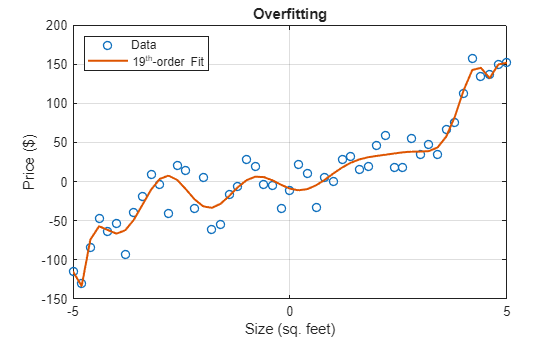

load('polyfit_19.mat')
x1_val = (house_size-mu(1))./mu(2);
xval_mtx = x1_val.^(19:-1:0);

figure;
plot(house_size, house_price, 'o', 'LineWidth', 1)
hold on
plot(house_size, sum(p.*xval_mtx,2), '-', 'LineWidth', 1.5)
xlabel('Size (sq. feet)')
ylabel('Price ($)')
grid on
hold off
legend('Data', '19^{th}-order Fit', 'Location','northwest')
title("Overfitting")

As we can see from the figure above, it seems like it is doing an extremely good job modeling the training data. Also, we can say that the cost function values are smaller than the goodfit since the model wraps the training data points better than the goodfit curve. The model above also has some interesting inconsistencies for instance even though some data points have larger house size values, their value is less than the other houses with smaller sizes, which might indicate that this particular model might not be a best model to predict the house prices based on the sizes. In technical terms, we can say that this model **overfits** the data, which means that the model represents/fits the training data almost **too well**. Another problem is that the model might not do well under the test set showing lower generalization capability to capture the underlying trends. In other words, we can say that this model has a **high variance**.

The problem here is that the model tries to fit the training data really hard, which results very low performance if the test data is even slightly different than the training data. If two separate machine learning engieers tries to fit this 19-th order polynomial curve, they might  end up having very different curves. This high variability suggest the high variance of the overfitting scenarios. Our main target in solving machine learning problems is to find a model that exactly fits the underlying trends ("Goodfit") based on the training and test datasets (**low bias and low variance**).

- So far we've investigated underfitting, overfitting, and goodfitting for linear regression. Let's now investigate a classification example with two features $x_1$ and $x_2$.

### Logistic Regression

Let's load the Fisher's Iris dataset and filter it for only petal length and petal width,

load('fisheriris_versicolor_virginica_petal.mat')

Let's min-max normalize the data to make the visualization simpler,

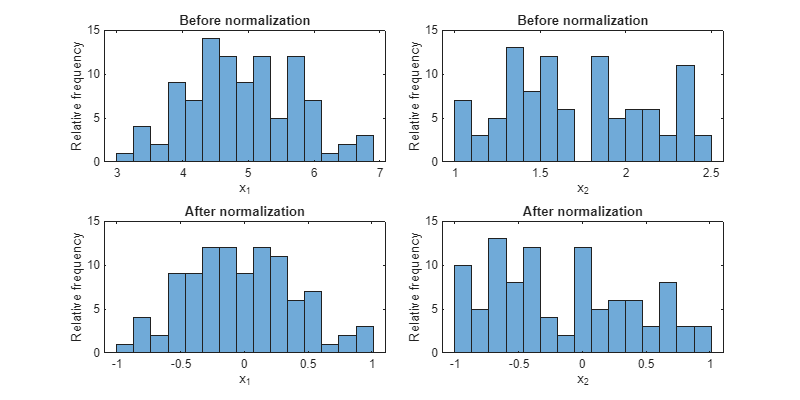

% min-max normalization
f = figure;
tiledlayout(2, 2, "TileSpacing", "compact")
nexttile
histogram(X_train(:,1), 15)
xlabel("x_1")
ylabel("Relative frequency")
title("Before normalization")

nexttile
histogram(X_train(:,2), 15)
xlabel("x_2")
ylabel("Relative frequency")
title("Before normalization")

X_train = normalizeFeatures(X_train, method="min-max");

nexttile
histogram(X_train(:,1), 15)
xlabel("x_1")
ylabel("Relative frequency")
title("After normalization")

nexttile
histogram(X_train(:,2), 15)
xlabel("x_2")
ylabel("Relative frequency")
title("After normalization")

f.Position = [0 0 800 400];

Let's plot the data,

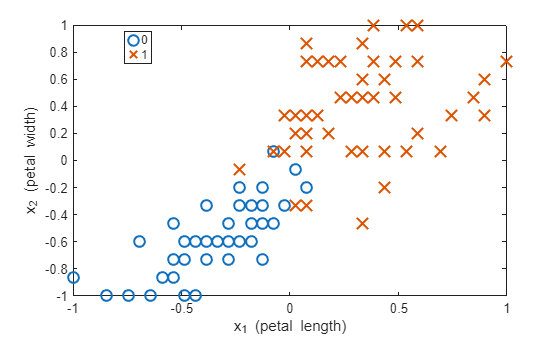

figure;
hBinaryScatter(X_train, y_train, {'o', 'x'}, {co(1,:), co(2,:)}, 8);
xlabel('x_1 (petal length)')
ylabel('x_2 (petal width)')
legend([repmat("",1,(length(X_train)/2)-1), "0", repmat("",1,(length(X_train)/2)-1), "1"], "Location", "best")

where the O's represent the petal length and width for Versicolor and X's represent Virginica. Our goal is to classify a given sample based on its petal length and width to determine its species.

- Our goal is to find a function that would take the petal length and width of the sample, $\mathbf{x} = (x_1, x_2)$, as an input and outputs a probability of the sample being a member of X (Virginica), $\hat{y} = P(y=1~|~\mathbf{x})$.

#### Logistic Regression Refresher and Visualise the Decision Regions of a Classifier

Logistic regression binary classification model takes the input features vector, $\mathbf{x}^{(i)} = [x_1^{(i)}~x_2^{(i)}~\cdots\ x_{j}^{(i)}]$, and returns the probability value $\hat{y}^{(i)} = f_{\mathbf{w},b}(\mathbf{x}^{(i)})$ that represents the probability, $P(y^{(i)}=1 ~|~ \mathbf{x^{(i)}})$, by finding the set of parameters, $\mathbf{w} = [w_1~w_2~\cdots~w_j]^{\text{T}}$ and $b$, to minimize the difference between $y^{(i)}$ (true label) and $\hat{y}^{(i)}$ (estimated label).

Similar to the linear regression, weighted and biased sum of the input features could be given by,


$$z = \mathbf{x}^{(i)}\mathbf{w} + b = w_1x^{(i)}_1 +  w_2x^{(i)}_2 + \cdots +  w_jx^{(i)}_j + b$$


Also, the relationship between the input features and the predicted logit or log-odds ($z$) is as follows:

$z = \text{logit}(\hat{y}^{(i)})= \ln \frac{P(y^{(i)}=1 ~|~ \mathbf{x}^{(i)})}{1-P(y^{(i)}=1 ~|~ \mathbf{x}^{(i)})} = \ln \frac{\hat{y}^{(i)}}{1-\hat{y}^{(i)}}$,

where the definition of logit or log-odds is given by $\text{logit} (p) = \ln \frac{p}{1-p} \quad \text{for } p\in(0,1)$. Note that the logit function is the inverse of the standard logistic function (sigmoid). Also note that the superscripts will be dropped for brevity. We can arrange the above expression as follows:


$$e^{z} = \frac{\hat{y}}{1-\hat{y}} \quad \rightarrow \quad  e^{z} - e^{z}\hat{y} = \hat{y} \quad \rightarrow \quad \hat{y}\left( 1 + e^{z} \right) = e^{z}$$


The expression above will directly indicate that $\hat{y} = \text{logit}(\hat{y}) =  \frac{1}{1+e^{-z}}$. Note that the relationship between the input features ($x_j ~~ \text{for}  ~~ j\in\{ 1,2,\cdots, n \}$) and the log-odds ($z$) is linear.

In particular, for a two-dimensional problem, the log-odds become,

$z = w_1x_1 + w_2x_2 + b$.

- It is sometimes useful to be able to visualize the the boundary line dividing the input space in which points are classified as belonging to the class of interest, $P(y=1 ~ | ~ \mathbf{x}^{(i)})$, from that space in which points do not.

- This could be achieved by calculating the prediciton associated with $\hat{y}$ for a mesh/surface $(x_1, x_2)$ points and plotting contour plot.

We know that the classification/decision making in logistic regression works as follows:

$y = 
\left\{
    \begin{array}{lr}
        1, & \text{if } \hat{y} \geq 0.5  \\
        0, & \text{if } \hat{y} < 0.5
    \end{array}$ , 

where$\hat{y} = \text{logit}(\hat{y}) =  \frac{1}{1+e^{-z}} = \frac{1}{1+e^{-(w_1x_1+w_2x_2+b)}}$

Let's brute force the mesh $(x_1, x_2)$ for the parameterization of $w_1=1$, $w_2 = 1$, and $b = 0$.

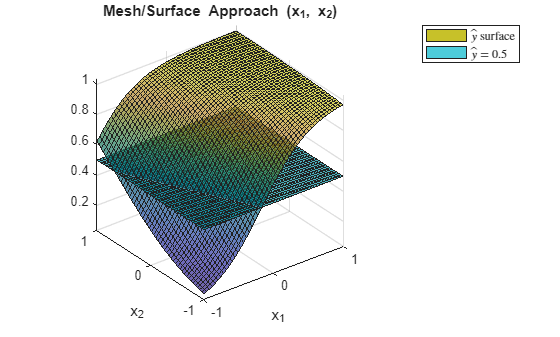

w1 = 3;
w2 = 1.5;
b = 2;

[x1, x2] = meshgrid(linspace(-1, 1, 50));
z = x1.*w1 + x2.*w2 + b;
y_hat = sigma(z);

figure;
surf(x1, x2, y_hat, 'FaceAlpha', 0.7);
hold on
surf(x1, x2, 0.5.*ones(size(y_hat)), 'FaceAlpha', 0.7)
hold off
xlabel('x_1')
ylabel('x_2')
title('Mesh/Surface Approach (x_1, x_2)')
legend('$\hat{y}$ surface', '$\hat{y}= 0.5$', 'Interpreter', 'latex');
view(3); camlight; axis vis3d

Let's run the stochastic gradient descent (SGD) algorithm on this logistic regression problem and visualize the decision boundary.

w_init = [0; 0]; % zero initialization
b_init = 0; % zero initialization
alpha = 0.1;
numIters = 10000;
[J_vec, w_vec, b] = hLogisticRegression(X_train, y_train, w_init, b_init, LearnRate=alpha, MaxIter=numIters);

Iteration:     0 -- w_vec: [  +0.0166  +0.0233  ] | b:  +0.0000 | Cost (J):  0.69314718 
Iteration:  1000 -- w_vec: [  +3.3381  +4.2952  ] | b:  +0.6207 | Cost (J):  0.15111504 
Iteration:  2000 -- w_vec: [  +4.3741  +5.2930  ] | b:  +0.8347 | Cost (J):  0.12931347 
Iteration:  3000 -- w_vec: [  +5.0900  +5.8573  ] | b:  +0.9618 | Cost (J):  0.12074515 
Iteration:  4000 -- w_vec: [  +5.6533  +6.2311  ] | b:  +1.0491 | Cost (J):  0.11607000 
Iteration:  5000 -- w_vec: [  +6.1222  +6.4984  ] | b:  +1.1135 | Cost (J):  0.11310350 
Iteration:  6000 -- w_vec: [  +6.5250  +6.6987  ] | b:  +1.1631 | Cost (J):  0.11104978 
Iteration:  7000 -- w_vec: [  +6.8778  +6.8538  ] | b:  +1.2024 | Cost (J):  0.10954586 
Iteration:  8000 -- w_vec: [  +7.1910  +6.9769  ] | b:  +1.2345 | Cost (J):  0.10840107 
Iteration:  9000 -- w_vec: [  +7.4717  +7.0767  ] | b:  +1.2610 | Cost (J):  0.10750491 
Iteration:  9999 -- w_vec: [  +7.7251  +7.1587  ] | b:  +1.2833 | Cost (J):  0.10678911 

----------
Terminati

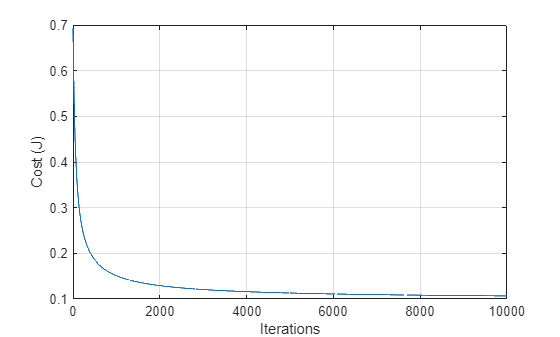

figure;
plot(1:length(J_vec), J_vec)
xlabel('Iterations')
ylabel('Cost (J)')
grid on

#### Alternative Way to Visualize 2D Decision Boundary

Alternatively, one can think of decision boundary as the line $x_2 = mx_1 + c$, being defined by the points for which $\hat{y} = 0.5$ or $z = 0$. We can find the line intercept $c$ and slope $m$ terms as follows: 

- For $x_1 = 0$, we have $x_2 = c$ (the $x_2$ axis intercept) and$z = 0  = 0\cdot w_1 + c\cdot w_2 + b \quad \rightarrow \quad c = -b / w_2$.

- For the slope, we will need two distinctive points on the decision boundary, $(x_1^a, x_2^a)$ and $(x_1^b, x_2^b)$, so that $m = (x_2^b- x_2^a) / (x_1^b - x_1^a)$. We know that $z = 0$ for any point on the decision boundary. Therefore, $0 = x_1^a w_1 + x_2^aw_2 + b$ and $0 = x_1^b w_1 + x_2^b w_2 + b$, which also means that $w_1x_1^b + w_2x_2^b + b - \left(  w_1x_1^a + w_2x_2^a + b \right) = 0$. If we arrange the expression, $w_1x_1^b - w_1x_1^a+ w_2x_2^b - w_2x_2^a = 0 ~ \rightarrow ~
w_1 \left( x_1^b - x_1^a \right) + w_2\left( x_2^b - x_2^a \right) = 0$. Thus, $\left( x_2^b-x_2^a \right)/ \left(x_1^b-x_1^a\right) = -w_1/w_2$, which is equal to $m$.

Since we know the slope and the intercept, we can get the final decision bounday line as, $x_2 = -\frac{w_1}{w_2}x_1 - \frac{b}{w_2}$.

**A simpler expression:** In a simpler way, we can derive the above expression as follows:

We have the following weighted sum (or logit of the output probabilities): $w_1x_1 + w_2 x_2 = 0$, where we know that this expression holds on the entire decision boundary line and we want to plot the relationship between $x_1$ and $x_2$. Let's fix one of the parameters $x_2 = -\frac{w_1}{w_2}x_1 - \frac{b}{w_2}$ , if we treat $x_1$ as the independent parameter and plot the results, we should be able to obtain the decision boundary.

#### Undefitting

Based on the dataset we've investigated above, we can try to fit a simple logistic model to the given data, $z = w_1x_1 + w_2x_2 + b$, where $f_{\mathbf{w},b}(\mathbf{x}) = \sigma(z) = g(z)$, where $\sigma(\cdot)$ and $g(\cdot)$ represents the sigmoid function.

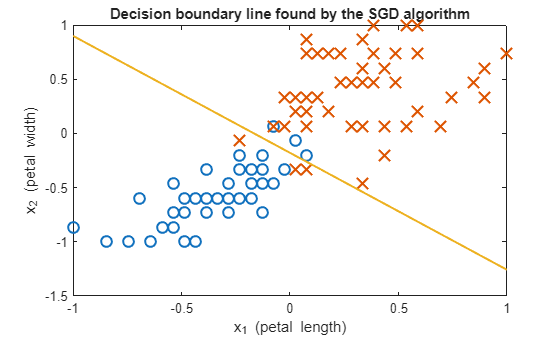

figure;
hBinaryScatter(X_train, y_train, {'o', 'x'}, {co(1,:), co(2,:)}, 8);
xlabel('x_1 (petal length)')
ylabel('x_2 (petal width)')
hold on
% decision boundary, w(1)*x1 + w(2)*x2 + b = 0
% x2 = -b/w(2) - w(1)/w(2)*x1
x1 = linspace(min(X_train, [], "all"), max(X_train, [], "all"), 50);
plot(x1, (-b/w_vec(2))-(w_vec(1)/w_vec(2)).*x1, 'Color', co(3,:), 'LineWidth', 1.5)
hold off
title("Decision boundary line found by the SGD algorithm")

The yellow curve is our decision boundary where the under the curve the samples are classified as O and above the curve the samples are classified as X. At a first glance we can say that this curve doesn't do a terrible job but it is not a good fit to the data. However, the model shows a high bias which means that it **underfits** the training data.

#### Goodfitting

Now, let's look at a more complex decision boundary, such as $z = w_1x_1 + w_2x_2 + w_3x_1^2 + w_4x_2^2 + w_5x_1x_2 + b$. Let's apply SGD algorithm first and use brute force the surface to plot the decision boundary,

w_init = [0; 0; 0; 0; 0]; % zero initialization
b_init = 0; % zero initialization
alpha = 0.1;
numIters = 1e5;
% Design the feature matrix such that [x1 x2 x1^2 x^2 x1*x2]
X_train_4 = [X_train(:,1) X_train(:,2) X_train(:,1).^2 X_train(:,2).^2 X_train(:,1).*X_train(:,2)];
[J_vec_1, w_vec_1, b_1] = hLogisticRegression(X_train_4, y_train, w_init, b_init, LearnRate=alpha, MaxIter=numIters, DispFreq=10000);

Iteration:      0 -- w_vec: [  +0.0166  +0.0233  -0.0002  -0.0030  -0.0026  ] | b:  +0.0000 | Cost (J):  0.69314718 
Iteration:  10000 -- w_vec: [  +7.4173  +7.0588  +0.6673  -0.4242  -2.0717  ] | b:  +1.2851 | Cost (J):  0.10494868 
Iteration:  20000 -- w_vec: [  +8.8018  +7.5477  +1.1188  +0.0322  -2.9580  ] | b:  +1.3646 | Cost (J):  0.10142272 
Iteration:  30000 -- w_vec: [  +9.3889  +7.7924  +1.5275  +0.4625  -3.6131  ] | b:  +1.3846 | Cost (J):  0.10021447 
Iteration:  40000 -- w_vec: [  +9.6412  +7.9649  +1.9141  +0.8648  -4.1675  ] | b:  +1.3868 | Cost (J):  0.09949739 
Iteration:  50000 -- w_vec: [  +9.7272  +8.1045  +2.2859  +1.2451  -4.6693  ] | b:  +1.3812 | Cost (J):  0.09893438 
Iteration:  60000 -- w_vec: [  +9.7243  +8.2260  +2.6456  +1.6075  -5.1405  ] | b:  +1.3719 | Cost (J):  0.09843627 
Iteration:  70000 -- w_vec: [  +9.6724  +8.3362  +2.9948  +1.9545  -5.5925  ] | b:  +1.3608 | Cost (J):  0.09797457 
Iteration:  80000 -- w_vec: [  +9.5937  +8.4387  +3.3344  +2.287

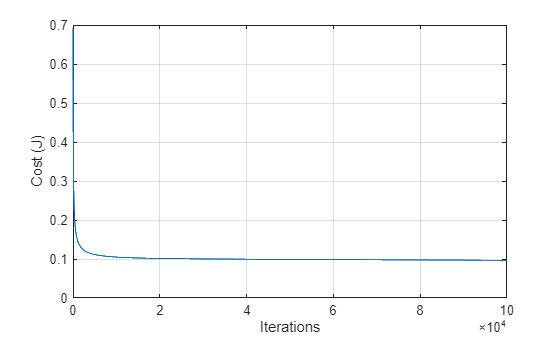

figure;
plot(1:length(J_vec_1), J_vec_1)
xlabel('Iterations')
ylabel('Cost (J)')
grid on

**Interactive Decision Boundary Visualization**

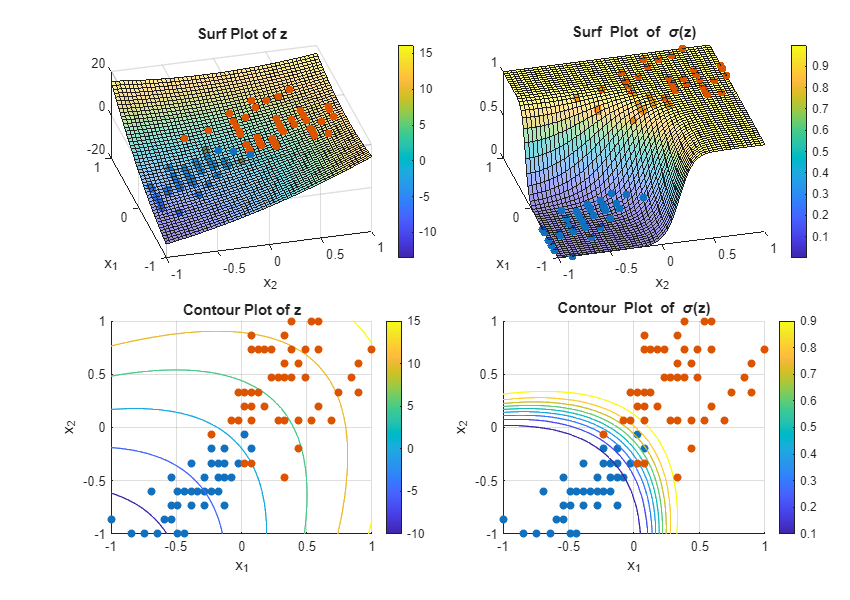

w_vec_1(1) = 7.7251;
w_vec_1(2) = 7.1587;
b_1        = 1.2833;
f = figure;
plotDecisionBoundarySurface(X_train, y_train, w_vec_1, b_1);
f.Position = [0 0 850 600];

We can see from the plots above that the this ellips-like decision boundary fits the data pretty good even though it doesn't perfectly classify every single sample correctly. The above "just-right" decision boundary will be able to generalize the new patient data the best, where the model is able to capture the underlying relationship between two classes and draw a decision boundary.

Now, let's try to only visualize the $z = 0$ or $\sigma(z) = 0.5$ curves,

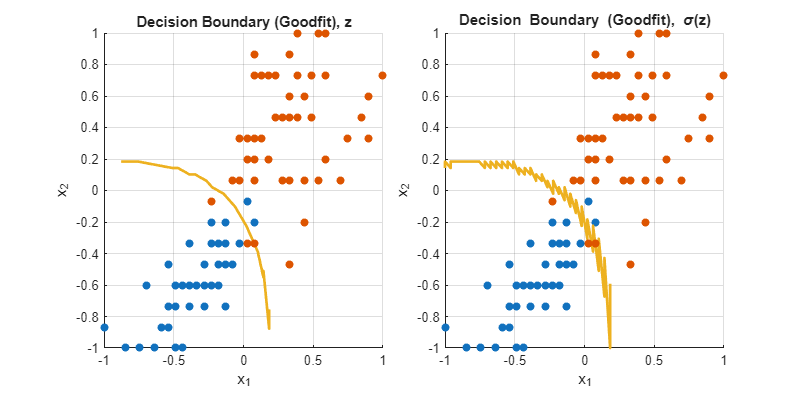

w_vec_1(1)  = 7.7251;
w_vec_1(2)  = 7.1587;
b_1         = 1.2833;
tolerance_1 = 0.11;
f = figure;
plotDecisionBoundaryLine(X_train, y_train, w_vec_1, b_1, tolerance_1);
f.Position = [0 0 800 400];
view([0 90])

Let's also try to visualize the contour plot between $z$-axis differences to find an other way to visualize the decision boundary/regions,

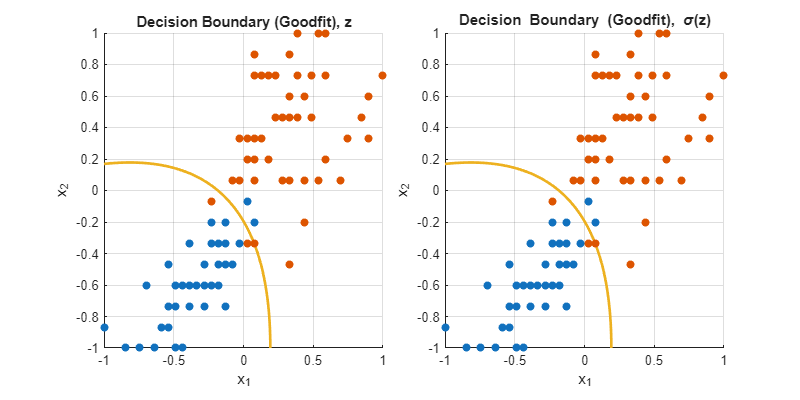

w_vec_1(1)  = 7.7251;
w_vec_1(2)  = 7.1587;
b_1         = 1.2833;
f = figure;
plotDecisionBoundaryLineUsingZDiff(X_train, y_train, w_vec_1, b_1);
f.Position = [0 0 800 400];

#### Overfitting

Finally, at the other extreme we can try to fit a very high order polynomial such as 


$$z = w_1x_1^3 + w_2x_1^3x_2 + w_3x_1^3x_2^2 + w_4x_1^3x_2^3 + w_5x_1^2 + w_6x_1^2x_2 \\
+ w_7x_1^2x_2^2 + w_8x_1^2x_2^3
+ w_9x_1 + w_{10}x_1x_2 + w_{11}x_1x_2^2
+ w_{12}x_1x_2^3 + w_{13}x_2 + w_{14}x_2^2 + w_{15}x_2^3 + b$$


How can we automate the above structure?

% Design the feature matrix such that
% | x1^(2) | x1^(2)*x2 | x1^(2)*x2^(2) | x1 | x1*x2 | x1*x2^(2) | x2 | x2^(2) |
X_train_test = [X_train(:,1).^2, X_train(:,1).^2.*X_train(:,2), X_train(:,1).^2.*X_train(:,2).^2,...
                X_train(:,1), X_train(:,1).*X_train(:,2), X_train(:,1).*X_train(:,2).^2, X_train(:,2), X_train(:,2).^2];
X_train_2 = polynomialFeatureExpansion2D(X_train, n=2);

| X1^(2)*X2^(0) | X1^(2)*X2^(1) | X1^(2)*X2^(2) | X1^(1)*X2^(0) | X1^(1)*X2^(1) | X1^(1)*X2^(2) | X1^(0)*X2^(1) | X1^(0)*X2^(2) | 


isequal(X_train_test, X_train_2)

ans = logical
   1


Let's use above polynomial expansion of the training data with SGD,

norder = 4; % nth order polynomial expansion

% 4-th order polynomial expansion of the parameters x_1 and x_2
X_train_4 = polynomialFeatureExpansion2D(X_train, n=norder);

| X1^(4)*X2^(0) | X1^(4)*X2^(1) | X1^(4)*X2^(2) | X1^(4)*X2^(3) | X1^(4)*X2^(4) | X1^(3)*X2^(0) | X1^(3)*X2^(1) | X1^(3)*X2^(2) | X1^(3)*X2^(3) | X1^(3)*X2^(4) | X1^(2)*X2^(0) | X1^(2)*X2^(1) | X1^(2)*X2^(2) | X1^(2)*X2^(3) | X1^(2)*X2^(4) | X1^(1)*X2^(0) | X1^(1)*X2^(1) | X1^(1)*X2^(2) | X1^(1)*X2^(3) | X1^(1)*X2^(4) | X1^(0)*X2^(1) | X1^(0)*X2^(2) | X1^(0)*X2^(3) | X1^(0)*X2^(4) | 


w_init = zeros(size(X_train_4, 2), 1); % zero initialization
b_init = 0; % zero initialization
alpha = 0.1; % learning rate
numIters = 1e6; % number of iterations
[J_vec_4, w_vec_4, b_4] = hLogisticRegression(X_train_4, y_train, w_init, b_init, LearnRate=alpha, MaxIter=numIters, DispFreq=1e5);

Iteration:       0 -- w_vec: [  +0.0002  +0.0028  -0.0009  +0.0019  -0.0010  +0.0057  -0.0009  +0.0030  -0.0012  +0.0023  -0.0002  +0.0056  -0.0016  +0.0037  -0.0016  +0.0166  -0.0026  +0.0075  -0.0022  +0.0052  +0.0233  -0.0030  +0.0121  -0.0022  ] | b:  +0.0000 | Cost (J):  0.69314718 
Iteration:  100000 -- w_vec: [  +0.4995  +0.1232  +0.0027  +0.0786  -0.0242  +1.1141  -0.4200  +0.3790  -0.1277  +0.1472  +3.9469  +0.2805  +0.0375  +0.1780  -0.0298  +8.9871  -6.5283  +3.8846  -1.4019  +0.9254  +8.5471  +3.1142  +0.6608  +0.2973  ] | b:  +1.3039 | Cost (J):  0.09579351 
Iteration:  200000 -- w_vec: [  +0.7140  +0.1188  +0.0026  +0.0791  -0.0245  +0.9084  -0.5645  +0.4618  -0.1635  +0.1639  +6.7246  +0.3908  -0.0350  +0.2109  -0.0433  +7.9812 -10.1953  +5.8965  -2.2004  +1.2710  +9.3491  +5.8603  +0.1885  +0.3779  ] | b:  +1.1941 | Cost (J):  0.09222632 
Iteration:  300000 -- w_vec: [  +0.8884  +0.1296  -0.0042  +0.0825  -0.0261  +0.6553  -0.6713  +0.5270  -0.1914  +0.1770  +9.1209  +0

% Calculate the decision boundary contour
[x1_loc, x2_loc, z_loc] = decisionBoundaryLineUsingZDiff(X_train_4, w_vec_4, b_4, n=norder, func="sigmoid");

X1^(4)*X2^(0) | X1^(4)*X2^(1) | X1^(4)*X2^(2) | X1^(4)*X2^(3) | X1^(4)*X2^(4) | X1^(3)*X2^(0) | X1^(3)*X2^(1) | X1^(3)*X2^(2) | X1^(3)*X2^(3) | X1^(3)*X2^(4) | X1^(2)*X2^(0) | X1^(2)*X2^(1) | X1^(2)*X2^(2) | X1^(2)*X2^(3) | X1^(2)*X2^(4) | X1^(1)*X2^(0) | X1^(1)*X2^(1) | X1^(1)*X2^(2) | X1^(1)*X2^(3) | X1^(1)*X2^(4) | X1^(0)*X2^(1) | X1^(0)*X2^(2) | X1^(0)*X2^(3) | X1^(0)*X2^(4) | 

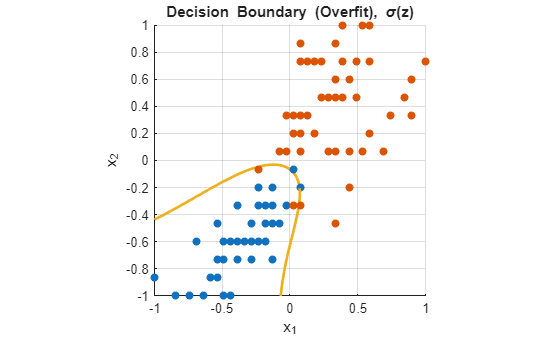

% Plot the decision boundary contour
figure;
hBinaryScatter3D(X_train, y_train, {co(1,:), co(2,:)}, 6);
hold on
grid on
line(x1_loc, x2_loc, z_loc, 'Color', co(3,:), 'LineWidth', 2);
hold off
xlabel("x_1")
ylabel("x_2")
view([0 90])
xlim([-1 1])
ylim([-1 1])
axis square
title("Decision Boundary (Overfit), \sigma(z)")

We can see from the above figure that the model is trying really hard to fit the countours around individual samples to **find a decision boundary that would fit our training data perfectly.** Having all these high order polynomial features (after the polynomial expansion of the training data) allows the model to choose a very (overly) complex decision boundary. If the features correspond to petal length and petal width an we are trying to determine whether a given plant is Versicolor (O) or Virginica (X), then this doesn't look like a good model for making predictions since this model shows a ovefitting and high variance, where the model won't be able to generalize well the new examples since it fitted itself to the training data very tightly.

## (Bonus Content)  The Optimal Model for the Logistic Regression Task

Related to the above investigation we go another step further and try to find an optimal model for a logistic regression task for the training data provided above,

alpha = 0.1; % learning rate
numIters = 1e6; % number of iterations
dispFreq = 1e5; % display frequency
C = orderedcolors("gem12");

f = figure;
hBinaryScatter3D(X_train, y_train, {C(1,:), C(2,:)}, 6);
hold on
for n = 1:2:15
    fprintf('\n n=%d\n', n);
    % nth order polynomial expansion of the parameters x_1 and x_2
    X_train_n = polynomialFeatureExpansion2D(X_train, n=n);

    % SGD
    w_init = zeros(size(X_train_n,2),1); % zero initialization
    b_init = 0; % zero initialization
    [J_vec_n, w_vec_n, b_n] = hLogisticRegression(X_train_n, y_train, w_init, b_init, LearnRate=alpha, MaxIter=numIters, DispFreq=dispFreq);
    fprintf('\n');

    % Calculate the decision boundary contour
    [x1_loc, x2_loc, z_loc] = decisionBoundaryLineUsingZDiff(X_train_n, w_vec_n, b_n, n=n, func="sigmoid");
    
    % Plot the decision boundary contour    
    line(x1_loc, x2_loc, z_loc, 'Color', C(mod(n-1,12)+1,:), 'LineWidth', 2, 'LineStyle', '-.');
    
end


 n=1


| X1^(1)*X2^(0) | X1^(1)*X2^(1) | X1^(0)*X2^(1) | 


Iteration:       0 -- w_vec: [  +0.0166  -0.0026  +0.0233  ] | b:  +0.0000 | Cost (J):  0.69314718 
Iteration:  100000 -- w_vec: [  +9.5887  -6.9179  +7.8202  ] | b:  +1.4573 | Cost (J):  0.09939539 
Iteration:  200000 -- w_vec: [  +8.8325 -10.4745  +7.8755  ] | b:  +1.4553 | Cost (J):  0.09806536 
Iteration:  300000 -- w_vec: [  +8.4440 -13.0417  +7.9919  ] | b:  +1.4725 | Cost (J):  0.09737847 
Iteration:  400000 -- w_vec: [  +8.3696 -14.4995  +8.1171  ] | b:  +1.4955 | Cost (J):  0.09715437 
Iteration:  500000 -- w_vec: [  +8.3929 -15.1467  +8.1896  ] | b:  +1.5096 | Cost (J):  0.09710910 
Iteration:  600000 -- w_vec: [  +8.4133 -15.4016  +8.2207  ] | b:  +1.5158 | Cost (J):  0.09710196 
Iteration:  700000 -- w_vec: [  +8.4227 -15.4980  +8.2328  ] | b:  +1.5182 | Cost (J):  0.09710093 
Iteration:  800000 -- w_vec: [  +8.4265 -15.5340  +8.2374  ] | b:  +1.5191 | Cost (J):  0.09710078 
Iteration:  900000 -- w_vec: [  +8.4279 -15.5474  +8.2391  ] | b:  +1.5194 | Cost (J):  0.09710076 


X1^(1)*X2^(0) | X1^(1)*X2^(1) | X1^(0)*X2^(1) | 


 n=3


| X1^(3)*X2^(0) | X1^(3)*X2^(1) | X1^(3)*X2^(2) | X1^(3)*X2^(3) | X1^(2)*X2^(0) | X1^(2)*X2^(1) | X1^(2)*X2^(2) | X1^(2)*X2^(3) | X1^(1)*X2^(0) | X1^(1)*X2^(1) | X1^(1)*X2^(2) | X1^(1)*X2^(3) | X1^(0)*X2^(1) | X1^(0)*X2^(2) | X1^(0)*X2^(3) | 


Iteration:       0 -- w_vec: [  +0.0057  -0.0009  +0.0030  -0.0012  -0.0002  +0.0056  -0.0016  +0.0037  +0.0166  -0.0026  +0.0075  -0.0022  +0.0233  -0.0030  +0.0121  ] | b:  +0.0000 | Cost (J):  0.69314718 
Iteration:  100000 -- w_vec: [  +1.1314  -0.4250  +0.3894  -0.1335  +3.9610  +0.2891  +0.0330  +0.1883  +8.9987  -6.5427  +3.9055  -1.4154  +8.5324  +3.1152  +0.6705  ] | b:  +1.3048 | Cost (J):  0.09583459 
Iteration:  200000 -- w_vec: [  +0.9285  -0.5704  +0.4728  -0.1695  +6.7535  +0.3945  -0.0369  +0.2200  +7.9899 -10.2118  +5.9191  -2.2138  +9.3405  +5.8886  +0.1810  ] | b:  +1.1941 | Cost (J):  0.09225678 
Iteration:  300000 -- w_vec: [  +0.6775  -0.6779  +0.5384  -0.1976  +9.1600  +0.6323  -0.1679  +0.2806  +7.2855 -13.5770  +7.7930  -2.9583  +9.9044  +8.0855  -0.0041  ] | b:  +1.1104 | Cost (J):  0.08955071 
Iteration:  400000 -- w_vec: [  +0.4027  -0.7640  +0.5942  -0.2214 +11.3817  +0.9169  -0.3201  +0.3514  +6.7531 -16.7208  +9.5757  -3.6712 +10.3308  +9.9462  -0.0044  ]

X1^(3)*X2^(0) | X1^(3)*X2^(1) | X1^(3)*X2^(2) | X1^(3)*X2^(3) | X1^(2)*X2^(0) | X1^(2)*X2^(1) | X1^(2)*X2^(2) | X1^(2)*X2^(3) | X1^(1)*X2^(0) | X1^(1)*X2^(1) | X1^(1)*X2^(2) | X1^(1)*X2^(3) | X1^(0)*X2^(1) | X1^(0)*X2^(2) | X1^(0)*X2^(3) | 


 n=5


| X1^(5)*X2^(0) | X1^(5)*X2^(1) | X1^(5)*X2^(2) | X1^(5)*X2^(3) | X1^(5)*X2^(4) | X1^(5)*X2^(5) | X1^(4)*X2^(0) | X1^(4)*X2^(1) | X1^(4)*X2^(2) | X1^(4)*X2^(3) | X1^(4)*X2^(4) | X1^(4)*X2^(5) | X1^(3)*X2^(0) | X1^(3)*X2^(1) | X1^(3)*X2^(2) | X1^(3)*X2^(3) | X1^(3)*X2^(4) | X1^(3)*X2^(5) | X1^(2)*X2^(0) | X1^(2)*X2^(1) | X1^(2)*X2^(2) | X1^(2)*X2^(3) | X1^(2)*X2^(4) | X1^(2)*X2^(5) | X1^(1)*X2^(0) | X1^(1)*X2^(1) | X1^(1)*X2^(2) | X1^(1)*X2^(3) | X1^(1)*X2^(4) | X1^(1)*X2^(5) | X1^(0)*X2^(1) | X1^(0)*X2^(2) | X1^(0)*X2^(3) | X1^(0)*X2^(4) | X1^(0)*X2^(5) | 


Iteration:       0 -- w_vec: [  +0.0032  -0.0004  +0.0018  -0.0008  +0.0014  -0.0008  +0.0002  +0.0028  -0.0009  +0.0019  -0.0010  +0.0016  +0.0057  -0.0009  +0.0030  -0.0012  +0.0023  -0.0012  -0.0002  +0.0056  -0.0016  +0.0037  -0.0016  +0.0030  +0.0166  -0.0026  +0.0075  -0.0022  +0.0052  -0.0019  +0.0233  -0.0030  +0.0121  -0.0022  +0.0086  ] | b:  +0.0000 | Cost (J):  0.69314718 
Iteration:  100000 -- w_vec: [  +0.3439  -0.0304  +0.0984  -0.0239  +0.0510  -0.0208  +0.5012  +0.1118  +0.0070  +0.0698  -0.0196  +0.0520  +1.0993  -0.4160  +0.3660  -0.1221  +0.1360  -0.0517  +3.9517  +0.2586  +0.0455  +0.1593  -0.0223  +0.1206  +8.9861  -6.5264  +3.8524  -1.3927  +0.8957  -0.3105  +8.5449  +3.1256  +0.5818  +0.3113  +0.6531  ] | b:  +1.3031 | Cost (J):  0.09578218 
Iteration:  200000 -- w_vec: [  +0.3569  -0.0448  +0.1060  -0.0273  +0.0527  -0.0216  +0.7157  +0.1073  +0.0071  +0.0701  -0.0197  +0.0523  +0.8933  -0.5601  +0.4486  -0.1576  +0.1525  -0.0595  +6.7292  +0.3676  -0.0257  +0.

X1^(5)*X2^(0) | X1^(5)*X2^(1) | X1^(5)*X2^(2) | X1^(5)*X2^(3) | X1^(5)*X2^(4) | X1^(5)*X2^(5) | X1^(4)*X2^(0) | X1^(4)*X2^(1) | X1^(4)*X2^(2) | X1^(4)*X2^(3) | X1^(4)*X2^(4) | X1^(4)*X2^(5) | X1^(3)*X2^(0) | X1^(3)*X2^(1) | X1^(3)*X2^(2) | X1^(3)*X2^(3) | X1^(3)*X2^(4) | X1^(3)*X2^(5) | X1^(2)*X2^(0) | X1^(2)*X2^(1) | X1^(2)*X2^(2) | X1^(2)*X2^(3) | X1^(2)*X2^(4) | X1^(2)*X2^(5) | X1^(1)*X2^(0) | X1^(1)*X2^(1) | X1^(1)*X2^(2) | X1^(1)*X2^(3) | X1^(1)*X2^(4) | X1^(1)*X2^(5) | X1^(0)*X2^(1) | X1^(0)*X2^(2) | X1^(0)*X2^(3) | X1^(0)*X2^(4) | X1^(0)*X2^(5) | 


 n=7


| X1^(7)*X2^(0) | X1^(7)*X2^(1) | X1^(7)*X2^(2) | X1^(7)*X2^(3) | X1^(7)*X2^(4) | X1^(7)*X2^(5) | X1^(7)*X2^(6) | X1^(7)*X2^(7) | X1^(6)*X2^(0) | X1^(6)*X2^(1) | X1^(6)*X2^(2) | X1^(6)*X2^(3) | X1^(6)*X2^(4) | X1^(6)*X2^(5) | X1^(6)*X2^(6) | X1^(6)*X2^(7) | X1^(5)*X2^(0) | X1^(5)*X2^(1) | X1^(5)*X2^(2) | X1^(5)*X2^(3) | X1^(5)*X2^(4) | X1^(5)*X2^(5) | X1^(5)*X2^(6) | X1^(5)*X2^(7) | X1^(4)*X2^(0) | X1^(4)*X2^(1) | X1^(4)*X2^(2) | X1^(4)*X2^(3) | X1^(4)*X2^(4) | X1^(4)*X2^(5) | X1^(4)*X2^(6) | X1^(4)*X2^(7) | X1^(3)*X2^(0) | X1^(3)*X2^(1) | X1^(3)*X2^(2) | X1^(3)*X2^(3) | X1^(3)*X2^(4) | X1^(3)*X2^(5) | X1^(3)*X2^(6) | X1^(3)*X2^(7) | X1^(2)*X2^(0) | X1^(2)*X2^(1) | X1^(2)*X2^(2) | X1^(2)*X2^(3) | X1^(2)*X2^(4) | X1^(2)*X2^(5) | X1^(2)*X2^(6) | X1^(2)*X2^(7) | X1^(1)*X2^(0) | X1^(1)*X2^(1) | X1^(1)*X2^(2) | X1^(1)*X2^(3) | X1^(1)*X2^(4) | X1^(1)*X2^(5) | X1^(1)*X2^(6) | X1^(1)*X2^(7) | X1^(0)*X2^(1) | X1^(0)*X2^(2) | X1^(0)*X2^(3) | X1^(0)*X2^(4) | X1^(0)*X2^(5) | X1^(0)*X2^(6) | X1^(0)

Iteration:       0 -- w_vec: [  +0.0023  -0.0002  +0.0013  -0.0005  +0.0010  -0.0006  +0.0008  -0.0006  +0.0002  +0.0019  -0.0005  +0.0013  -0.0007  +0.0010  -0.0007  +0.0009  +0.0032  -0.0004  +0.0018  -0.0008  +0.0014  -0.0008  +0.0012  -0.0008  +0.0002  +0.0028  -0.0009  +0.0019  -0.0010  +0.0016  -0.0010  +0.0014  +0.0057  -0.0009  +0.0030  -0.0012  +0.0023  -0.0012  +0.0019  -0.0012  -0.0002  +0.0056  -0.0016  +0.0037  -0.0016  +0.0030  -0.0015  +0.0026  +0.0166  -0.0026  +0.0075  -0.0022  +0.0052  -0.0019  +0.0043  -0.0018  +0.0233  -0.0030  +0.0121  -0.0022  +0.0086  -0.0020  +0.0071  ] | b:  +0.0000 | Cost (J):  0.69314718 
Iteration:  100000 -- w_vec: [  +0.1530  +0.0125  +0.0482  -0.0060  +0.0274  -0.0097  +0.0197  -0.0106  +0.1261  +0.0785  +0.0022  +0.0396  -0.0101  +0.0271  -0.0125  +0.0214  +0.3348  -0.0285  +0.0920  -0.0209  +0.0458  -0.0175  +0.0315  -0.0163  +0.5016  +0.1032  +0.0103  +0.0628  -0.0156  +0.0458  -0.0195  +0.0372  +1.0884  -0.4131  +0.3565  -0.1175  +0.1

X1^(7)*X2^(0) | X1^(7)*X2^(1) | X1^(7)*X2^(2) | X1^(7)*X2^(3) | X1^(7)*X2^(4) | X1^(7)*X2^(5) | X1^(7)*X2^(6) | X1^(7)*X2^(7) | X1^(6)*X2^(0) | X1^(6)*X2^(1) | X1^(6)*X2^(2) | X1^(6)*X2^(3) | X1^(6)*X2^(4) | X1^(6)*X2^(5) | X1^(6)*X2^(6) | X1^(6)*X2^(7) | X1^(5)*X2^(0) | X1^(5)*X2^(1) | X1^(5)*X2^(2) | X1^(5)*X2^(3) | X1^(5)*X2^(4) | X1^(5)*X2^(5) | X1^(5)*X2^(6) | X1^(5)*X2^(7) | X1^(4)*X2^(0) | X1^(4)*X2^(1) | X1^(4)*X2^(2) | X1^(4)*X2^(3) | X1^(4)*X2^(4) | X1^(4)*X2^(5) | X1^(4)*X2^(6) | X1^(4)*X2^(7) | X1^(3)*X2^(0) | X1^(3)*X2^(1) | X1^(3)*X2^(2) | X1^(3)*X2^(3) | X1^(3)*X2^(4) | X1^(3)*X2^(5) | X1^(3)*X2^(6) | X1^(3)*X2^(7) | X1^(2)*X2^(0) | X1^(2)*X2^(1) | X1^(2)*X2^(2) | X1^(2)*X2^(3) | X1^(2)*X2^(4) | X1^(2)*X2^(5) | X1^(2)*X2^(6) | X1^(2)*X2^(7) | X1^(1)*X2^(0) | X1^(1)*X2^(1) | X1^(1)*X2^(2) | X1^(1)*X2^(3) | X1^(1)*X2^(4) | X1^(1)*X2^(5) | X1^(1)*X2^(6) | X1^(1)*X2^(7) | X1^(0)*X2^(1) | X1^(0)*X2^(2) | X1^(0)*X2^(3) | X1^(0)*X2^(4) | X1^(0)*X2^(5) | X1^(0)*X2^(6) | X1^(0)*X


 n=9


| X1^(9)*X2^(0) | X1^(9)*X2^(1) | X1^(9)*X2^(2) | X1^(9)*X2^(3) | X1^(9)*X2^(4) | X1^(9)*X2^(5) | X1^(9)*X2^(6) | X1^(9)*X2^(7) | X1^(9)*X2^(8) | X1^(9)*X2^(9) | X1^(8)*X2^(0) | X1^(8)*X2^(1) | X1^(8)*X2^(2) | X1^(8)*X2^(3) | X1^(8)*X2^(4) | X1^(8)*X2^(5) | X1^(8)*X2^(6) | X1^(8)*X2^(7) | X1^(8)*X2^(8) | X1^(8)*X2^(9) | X1^(7)*X2^(0) | X1^(7)*X2^(1) | X1^(7)*X2^(2) | X1^(7)*X2^(3) | X1^(7)*X2^(4) | X1^(7)*X2^(5) | X1^(7)*X2^(6) | X1^(7)*X2^(7) | X1^(7)*X2^(8) | X1^(7)*X2^(9) | X1^(6)*X2^(0) | X1^(6)*X2^(1) | X1^(6)*X2^(2) | X1^(6)*X2^(3) | X1^(6)*X2^(4) | X1^(6)*X2^(5) | X1^(6)*X2^(6) | X1^(6)*X2^(7) | X1^(6)*X2^(8) | X1^(6)*X2^(9) | X1^(5)*X2^(0) | X1^(5)*X2^(1) | X1^(5)*X2^(2) | X1^(5)*X2^(3) | X1^(5)*X2^(4) | X1^(5)*X2^(5) | X1^(5)*X2^(6) | X1^(5)*X2^(7) | X1^(5)*X2^(8) | X1^(5)*X2^(9) | X1^(4)*X2^(0) | X1^(4)*X2^(1) | X1^(4)*X2^(2) | X1^(4)*X2^(3) | X1^(4)*X2^(4) | X1^(4)*X2^(5) | X1^(4)*X2^(6) | X1^(4)*X2^(7) | X1^(4)*X2^(8) | X1^(4)*X2^(9) | X1^(3)*X2^(0) | X1^(3)*X2^(1) | X1^(3)

Iteration:       0 -- w_vec: [  +0.0019  -0.0001  +0.0011  -0.0004  +0.0008  -0.0004  +0.0006  -0.0004  +0.0005  -0.0004  +0.0002  +0.0015  -0.0004  +0.0010  -0.0005  +0.0008  -0.0005  +0.0006  -0.0005  +0.0006  +0.0023  -0.0002  +0.0013  -0.0005  +0.0010  -0.0006  +0.0008  -0.0006  +0.0007  -0.0006  +0.0002  +0.0019  -0.0005  +0.0013  -0.0007  +0.0010  -0.0007  +0.0009  -0.0007  +0.0008  +0.0032  -0.0004  +0.0018  -0.0008  +0.0014  -0.0008  +0.0012  -0.0008  +0.0010  -0.0008  +0.0002  +0.0028  -0.0009  +0.0019  -0.0010  +0.0016  -0.0010  +0.0014  -0.0010  +0.0013  +0.0057  -0.0009  +0.0030  -0.0012  +0.0023  -0.0012  +0.0019  -0.0012  +0.0018  -0.0012  -0.0002  +0.0056  -0.0016  +0.0037  -0.0016  +0.0030  -0.0015  +0.0026  -0.0015  +0.0024  +0.0166  -0.0026  +0.0075  -0.0022  +0.0052  -0.0019  +0.0043  -0.0018  +0.0039  -0.0018  +0.0233  -0.0030  +0.0121  -0.0022  +0.0086  -0.0020  +0.0071  -0.0020  +0.0063  ] | b:  +0.0000 | Cost (J):  0.69314718 
Iteration:  100000 -- w_vec: [  +0.0

X1^(9)*X2^(0) | X1^(9)*X2^(1) | X1^(9)*X2^(2) | X1^(9)*X2^(3) | X1^(9)*X2^(4) | X1^(9)*X2^(5) | X1^(9)*X2^(6) | X1^(9)*X2^(7) | X1^(9)*X2^(8) | X1^(9)*X2^(9) | X1^(8)*X2^(0) | X1^(8)*X2^(1) | X1^(8)*X2^(2) | X1^(8)*X2^(3) | X1^(8)*X2^(4) | X1^(8)*X2^(5) | X1^(8)*X2^(6) | X1^(8)*X2^(7) | X1^(8)*X2^(8) | X1^(8)*X2^(9) | X1^(7)*X2^(0) | X1^(7)*X2^(1) | X1^(7)*X2^(2) | X1^(7)*X2^(3) | X1^(7)*X2^(4) | X1^(7)*X2^(5) | X1^(7)*X2^(6) | X1^(7)*X2^(7) | X1^(7)*X2^(8) | X1^(7)*X2^(9) | X1^(6)*X2^(0) | X1^(6)*X2^(1) | X1^(6)*X2^(2) | X1^(6)*X2^(3) | X1^(6)*X2^(4) | X1^(6)*X2^(5) | X1^(6)*X2^(6) | X1^(6)*X2^(7) | X1^(6)*X2^(8) | X1^(6)*X2^(9) | X1^(5)*X2^(0) | X1^(5)*X2^(1) | X1^(5)*X2^(2) | X1^(5)*X2^(3) | X1^(5)*X2^(4) | X1^(5)*X2^(5) | X1^(5)*X2^(6) | X1^(5)*X2^(7) | X1^(5)*X2^(8) | X1^(5)*X2^(9) | X1^(4)*X2^(0) | X1^(4)*X2^(1) | X1^(4)*X2^(2) | X1^(4)*X2^(3) | X1^(4)*X2^(4) | X1^(4)*X2^(5) | X1^(4)*X2^(6) | X1^(4)*X2^(7) | X1^(4)*X2^(8) | X1^(4)*X2^(9) | X1^(3)*X2^(0) | X1^(3)*X2^(1) | X1^(3)*X


 n=11


| X1^(11)*X2^(0) | X1^(11)*X2^(1) | X1^(11)*X2^(2) | X1^(11)*X2^(3) | X1^(11)*X2^(4) | X1^(11)*X2^(5) | X1^(11)*X2^(6) | X1^(11)*X2^(7) | X1^(11)*X2^(8) | X1^(11)*X2^(9) | X1^(11)*X2^(10) | X1^(11)*X2^(11) | X1^(10)*X2^(0) | X1^(10)*X2^(1) | X1^(10)*X2^(2) | X1^(10)*X2^(3) | X1^(10)*X2^(4) | X1^(10)*X2^(5) | X1^(10)*X2^(6) | X1^(10)*X2^(7) | X1^(10)*X2^(8) | X1^(10)*X2^(9) | X1^(10)*X2^(10) | X1^(10)*X2^(11) | X1^(9)*X2^(0) | X1^(9)*X2^(1) | X1^(9)*X2^(2) | X1^(9)*X2^(3) | X1^(9)*X2^(4) | X1^(9)*X2^(5) | X1^(9)*X2^(6) | X1^(9)*X2^(7) | X1^(9)*X2^(8) | X1^(9)*X2^(9) | X1^(9)*X2^(10) | X1^(9)*X2^(11) | X1^(8)*X2^(0) | X1^(8)*X2^(1) | X1^(8)*X2^(2) | X1^(8)*X2^(3) | X1^(8)*X2^(4) | X1^(8)*X2^(5) | X1^(8)*X2^(6) | X1^(8)*X2^(7) | X1^(8)*X2^(8) | X1^(8)*X2^(9) | X1^(8)*X2^(10) | X1^(8)*X2^(11) | X1^(7)*X2^(0) | X1^(7)*X2^(1) | X1^(7)*X2^(2) | X1^(7)*X2^(3) | X1^(7)*X2^(4) | X1^(7)*X2^(5) | X1^(7)*X2^(6) | X1^(7)*X2^(7) | X1^(7)*X2^(8) | X1^(7)*X2^(9) | X1^(7)*X2^(10) | X1^(7)*X2^(11) | X1^(

Iteration:       0 -- w_vec: [  +0.0016  -0.0001  +0.0009  -0.0003  +0.0007  -0.0003  +0.0005  -0.0003  +0.0004  -0.0003  +0.0003  -0.0003  +0.0002  +0.0013  -0.0003  +0.0008  -0.0004  +0.0006  -0.0004  +0.0005  -0.0004  +0.0004  -0.0003  +0.0004  +0.0019  -0.0001  +0.0011  -0.0004  +0.0008  -0.0004  +0.0006  -0.0004  +0.0005  -0.0004  +0.0005  -0.0004  +0.0002  +0.0015  -0.0004  +0.0010  -0.0005  +0.0008  -0.0005  +0.0006  -0.0005  +0.0006  -0.0005  +0.0005  +0.0023  -0.0002  +0.0013  -0.0005  +0.0010  -0.0006  +0.0008  -0.0006  +0.0007  -0.0006  +0.0006  -0.0005  +0.0002  +0.0019  -0.0005  +0.0013  -0.0007  +0.0010  -0.0007  +0.0009  -0.0007  +0.0008  -0.0006  +0.0007  +0.0032  -0.0004  +0.0018  -0.0008  +0.0014  -0.0008  +0.0012  -0.0008  +0.0010  -0.0008  +0.0010  -0.0008  +0.0002  +0.0028  -0.0009  +0.0019  -0.0010  +0.0016  -0.0010  +0.0014  -0.0010  +0.0013  -0.0010  +0.0012  +0.0057  -0.0009  +0.0030  -0.0012  +0.0023  -0.0012  +0.0019  -0.0012  +0.0018  -0.0012  +0.0017  -0.00

X1^(11)*X2^(0) | X1^(11)*X2^(1) | X1^(11)*X2^(2) | X1^(11)*X2^(3) | X1^(11)*X2^(4) | X1^(11)*X2^(5) | X1^(11)*X2^(6) | X1^(11)*X2^(7) | X1^(11)*X2^(8) | X1^(11)*X2^(9) | X1^(11)*X2^(10) | X1^(11)*X2^(11) | X1^(10)*X2^(0) | X1^(10)*X2^(1) | X1^(10)*X2^(2) | X1^(10)*X2^(3) | X1^(10)*X2^(4) | X1^(10)*X2^(5) | X1^(10)*X2^(6) | X1^(10)*X2^(7) | X1^(10)*X2^(8) | X1^(10)*X2^(9) | X1^(10)*X2^(10) | X1^(10)*X2^(11) | X1^(9)*X2^(0) | X1^(9)*X2^(1) | X1^(9)*X2^(2) | X1^(9)*X2^(3) | X1^(9)*X2^(4) | X1^(9)*X2^(5) | X1^(9)*X2^(6) | X1^(9)*X2^(7) | X1^(9)*X2^(8) | X1^(9)*X2^(9) | X1^(9)*X2^(10) | X1^(9)*X2^(11) | X1^(8)*X2^(0) | X1^(8)*X2^(1) | X1^(8)*X2^(2) | X1^(8)*X2^(3) | X1^(8)*X2^(4) | X1^(8)*X2^(5) | X1^(8)*X2^(6) | X1^(8)*X2^(7) | X1^(8)*X2^(8) | X1^(8)*X2^(9) | X1^(8)*X2^(10) | X1^(8)*X2^(11) | X1^(7)*X2^(0) | X1^(7)*X2^(1) | X1^(7)*X2^(2) | X1^(7)*X2^(3) | X1^(7)*X2^(4) | X1^(7)*X2^(5) | X1^(7)*X2^(6) | X1^(7)*X2^(7) | X1^(7)*X2^(8) | X1^(7)*X2^(9) | X1^(7)*X2^(10) | X1^(7)*X2^(11) | X1^(6)


 n=13


| X1^(13)*X2^(0) | X1^(13)*X2^(1) | X1^(13)*X2^(2) | X1^(13)*X2^(3) | X1^(13)*X2^(4) | X1^(13)*X2^(5) | X1^(13)*X2^(6) | X1^(13)*X2^(7) | X1^(13)*X2^(8) | X1^(13)*X2^(9) | X1^(13)*X2^(10) | X1^(13)*X2^(11) | X1^(13)*X2^(12) | X1^(13)*X2^(13) | X1^(12)*X2^(0) | X1^(12)*X2^(1) | X1^(12)*X2^(2) | X1^(12)*X2^(3) | X1^(12)*X2^(4) | X1^(12)*X2^(5) | X1^(12)*X2^(6) | X1^(12)*X2^(7) | X1^(12)*X2^(8) | X1^(12)*X2^(9) | X1^(12)*X2^(10) | X1^(12)*X2^(11) | X1^(12)*X2^(12) | X1^(12)*X2^(13) | X1^(11)*X2^(0) | X1^(11)*X2^(1) | X1^(11)*X2^(2) | X1^(11)*X2^(3) | X1^(11)*X2^(4) | X1^(11)*X2^(5) | X1^(11)*X2^(6) | X1^(11)*X2^(7) | X1^(11)*X2^(8) | X1^(11)*X2^(9) | X1^(11)*X2^(10) | X1^(11)*X2^(11) | X1^(11)*X2^(12) | X1^(11)*X2^(13) | X1^(10)*X2^(0) | X1^(10)*X2^(1) | X1^(10)*X2^(2) | X1^(10)*X2^(3) | X1^(10)*X2^(4) | X1^(10)*X2^(5) | X1^(10)*X2^(6) | X1^(10)*X2^(7) | X1^(10)*X2^(8) | X1^(10)*X2^(9) | X1^(10)*X2^(10) | X1^(10)*X2^(11) | X1^(10)*X2^(12) | X1^(10)*X2^(13) | X1^(9)*X2^(0) | X1^(9)*X2^(1) 

Iteration:       0 -- w_vec: [  +0.0015  -0.0001  +0.0009  -0.0002  +0.0006  -0.0003  +0.0004  -0.0003  +0.0003  -0.0002  +0.0003  -0.0002  +0.0002  -0.0002  +0.0002  +0.0011  -0.0002  +0.0007  -0.0003  +0.0005  -0.0003  +0.0004  -0.0003  +0.0003  -0.0003  +0.0003  -0.0002  +0.0003  +0.0016  -0.0001  +0.0009  -0.0003  +0.0007  -0.0003  +0.0005  -0.0003  +0.0004  -0.0003  +0.0003  -0.0003  +0.0003  -0.0003  +0.0002  +0.0013  -0.0003  +0.0008  -0.0004  +0.0006  -0.0004  +0.0005  -0.0004  +0.0004  -0.0003  +0.0004  -0.0003  +0.0003  +0.0019  -0.0001  +0.0011  -0.0004  +0.0008  -0.0004  +0.0006  -0.0004  +0.0005  -0.0004  +0.0005  -0.0004  +0.0004  -0.0004  +0.0002  +0.0015  -0.0004  +0.0010  -0.0005  +0.0008  -0.0005  +0.0006  -0.0005  +0.0006  -0.0005  +0.0005  -0.0004  +0.0005  +0.0023  -0.0002  +0.0013  -0.0005  +0.0010  -0.0006  +0.0008  -0.0006  +0.0007  -0.0006  +0.0006  -0.0005  +0.0006  -0.0005  +0.0002  +0.0019  -0.0005  +0.0013  -0.0007  +0.0010  -0.0007  +0.0009  -0.0007  +0.00

X1^(13)*X2^(0) | X1^(13)*X2^(1) | X1^(13)*X2^(2) | X1^(13)*X2^(3) | X1^(13)*X2^(4) | X1^(13)*X2^(5) | X1^(13)*X2^(6) | X1^(13)*X2^(7) | X1^(13)*X2^(8) | X1^(13)*X2^(9) | X1^(13)*X2^(10) | X1^(13)*X2^(11) | X1^(13)*X2^(12) | X1^(13)*X2^(13) | X1^(12)*X2^(0) | X1^(12)*X2^(1) | X1^(12)*X2^(2) | X1^(12)*X2^(3) | X1^(12)*X2^(4) | X1^(12)*X2^(5) | X1^(12)*X2^(6) | X1^(12)*X2^(7) | X1^(12)*X2^(8) | X1^(12)*X2^(9) | X1^(12)*X2^(10) | X1^(12)*X2^(11) | X1^(12)*X2^(12) | X1^(12)*X2^(13) | X1^(11)*X2^(0) | X1^(11)*X2^(1) | X1^(11)*X2^(2) | X1^(11)*X2^(3) | X1^(11)*X2^(4) | X1^(11)*X2^(5) | X1^(11)*X2^(6) | X1^(11)*X2^(7) | X1^(11)*X2^(8) | X1^(11)*X2^(9) | X1^(11)*X2^(10) | X1^(11)*X2^(11) | X1^(11)*X2^(12) | X1^(11)*X2^(13) | X1^(10)*X2^(0) | X1^(10)*X2^(1) | X1^(10)*X2^(2) | X1^(10)*X2^(3) | X1^(10)*X2^(4) | X1^(10)*X2^(5) | X1^(10)*X2^(6) | X1^(10)*X2^(7) | X1^(10)*X2^(8) | X1^(10)*X2^(9) | X1^(10)*X2^(10) | X1^(10)*X2^(11) | X1^(10)*X2^(12) | X1^(10)*X2^(13) | X1^(9)*X2^(0) | X1^(9)*X2^(1) | 


 n=15


| X1^(15)*X2^(0) | X1^(15)*X2^(1) | X1^(15)*X2^(2) | X1^(15)*X2^(3) | X1^(15)*X2^(4) | X1^(15)*X2^(5) | X1^(15)*X2^(6) | X1^(15)*X2^(7) | X1^(15)*X2^(8) | X1^(15)*X2^(9) | X1^(15)*X2^(10) | X1^(15)*X2^(11) | X1^(15)*X2^(12) | X1^(15)*X2^(13) | X1^(15)*X2^(14) | X1^(15)*X2^(15) | X1^(14)*X2^(0) | X1^(14)*X2^(1) | X1^(14)*X2^(2) | X1^(14)*X2^(3) | X1^(14)*X2^(4) | X1^(14)*X2^(5) | X1^(14)*X2^(6) | X1^(14)*X2^(7) | X1^(14)*X2^(8) | X1^(14)*X2^(9) | X1^(14)*X2^(10) | X1^(14)*X2^(11) | X1^(14)*X2^(12) | X1^(14)*X2^(13) | X1^(14)*X2^(14) | X1^(14)*X2^(15) | X1^(13)*X2^(0) | X1^(13)*X2^(1) | X1^(13)*X2^(2) | X1^(13)*X2^(3) | X1^(13)*X2^(4) | X1^(13)*X2^(5) | X1^(13)*X2^(6) | X1^(13)*X2^(7) | X1^(13)*X2^(8) | X1^(13)*X2^(9) | X1^(13)*X2^(10) | X1^(13)*X2^(11) | X1^(13)*X2^(12) | X1^(13)*X2^(13) | X1^(13)*X2^(14) | X1^(13)*X2^(15) | X1^(12)*X2^(0) | X1^(12)*X2^(1) | X1^(12)*X2^(2) | X1^(12)*X2^(3) | X1^(12)*X2^(4) | X1^(12)*X2^(5) | X1^(12)*X2^(6) | X1^(12)*X2^(7) | X1^(12)*X2^(8) | X1^(12)*X2^

Iteration:       0 -- w_vec: [  +0.0013  -0.0000  +0.0008  -0.0002  +0.0005  -0.0002  +0.0004  -0.0002  +0.0003  -0.0002  +0.0002  -0.0002  +0.0002  -0.0002  +0.0002  -0.0001  +0.0002  +0.0010  -0.0002  +0.0007  -0.0002  +0.0005  -0.0002  +0.0004  -0.0002  +0.0003  -0.0002  +0.0002  -0.0002  +0.0002  -0.0002  +0.0002  +0.0015  -0.0001  +0.0009  -0.0002  +0.0006  -0.0003  +0.0004  -0.0003  +0.0003  -0.0002  +0.0003  -0.0002  +0.0002  -0.0002  +0.0002  -0.0002  +0.0002  +0.0011  -0.0002  +0.0007  -0.0003  +0.0005  -0.0003  +0.0004  -0.0003  +0.0003  -0.0003  +0.0003  -0.0002  +0.0003  -0.0002  +0.0002  +0.0016  -0.0001  +0.0009  -0.0003  +0.0007  -0.0003  +0.0005  -0.0003  +0.0004  -0.0003  +0.0003  -0.0003  +0.0003  -0.0003  +0.0003  -0.0003  +0.0002  +0.0013  -0.0003  +0.0008  -0.0004  +0.0006  -0.0004  +0.0005  -0.0004  +0.0004  -0.0003  +0.0004  -0.0003  +0.0003  -0.0003  +0.0003  +0.0019  -0.0001  +0.0011  -0.0004  +0.0008  -0.0004  +0.0006  -0.0004  +0.0005  -0.0004  +0.0005  -0.00

X1^(15)*X2^(0) | X1^(15)*X2^(1) | X1^(15)*X2^(2) | X1^(15)*X2^(3) | X1^(15)*X2^(4) | X1^(15)*X2^(5) | X1^(15)*X2^(6) | X1^(15)*X2^(7) | X1^(15)*X2^(8) | X1^(15)*X2^(9) | X1^(15)*X2^(10) | X1^(15)*X2^(11) | X1^(15)*X2^(12) | X1^(15)*X2^(13) | X1^(15)*X2^(14) | X1^(15)*X2^(15) | X1^(14)*X2^(0) | X1^(14)*X2^(1) | X1^(14)*X2^(2) | X1^(14)*X2^(3) | X1^(14)*X2^(4) | X1^(14)*X2^(5) | X1^(14)*X2^(6) | X1^(14)*X2^(7) | X1^(14)*X2^(8) | X1^(14)*X2^(9) | X1^(14)*X2^(10) | X1^(14)*X2^(11) | X1^(14)*X2^(12) | X1^(14)*X2^(13) | X1^(14)*X2^(14) | X1^(14)*X2^(15) | X1^(13)*X2^(0) | X1^(13)*X2^(1) | X1^(13)*X2^(2) | X1^(13)*X2^(3) | X1^(13)*X2^(4) | X1^(13)*X2^(5) | X1^(13)*X2^(6) | X1^(13)*X2^(7) | X1^(13)*X2^(8) | X1^(13)*X2^(9) | X1^(13)*X2^(10) | X1^(13)*X2^(11) | X1^(13)*X2^(12) | X1^(13)*X2^(13) | X1^(13)*X2^(14) | X1^(13)*X2^(15) | X1^(12)*X2^(0) | X1^(12)*X2^(1) | X1^(12)*X2^(2) | X1^(12)*X2^(3) | X1^(12)*X2^(4) | X1^(12)*X2^(5) | X1^(12)*X2^(6) | X1^(12)*X2^(7) | X1^(12)*X2^(8) | X1^(12)*X2^(9

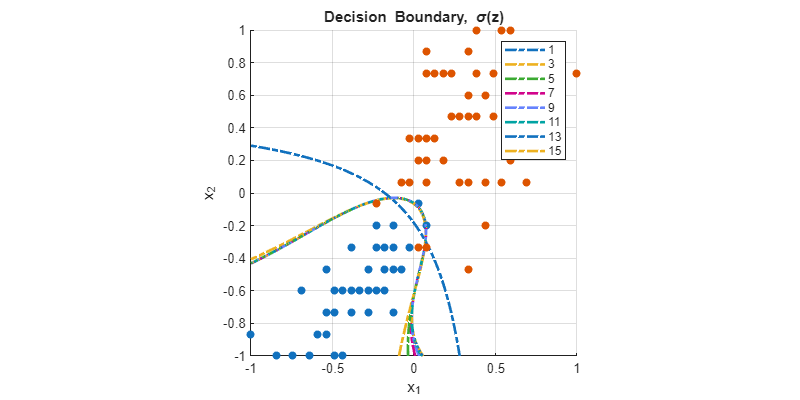

hold off
grid on
f.Position = [0 0 800 400];
view([0 90])
xlabel("x_1")
ylabel("x_2")
view([0 90])
xlim([-1 1])
ylim([-1 1])
axis square
title("Decision Boundary, \sigma(z)")
legend([repmat("",1,length(X_train)) string(1:2:15)])

## References

[1] Andew Ng, [Supervised Machine Learning: Regression and Classification](https://www.coursera.org/learn/machine-learning/home/welcome)

[2] [Plotting the decision boundary of a logistic regression model](https://scipython.com/blog/plotting-the-decision-boundary-of-a-logistic-regression-model/)

## Local Functions

function norminput = normalizeFeatures(input, opts)
arguments
    input
    opts.method
    opts.min {mustBeNumericOrLogical} = -1
    opts.max {mustBeNumericOrLogical} = 1
end
n = size(input, 2); % number of features per sample
norminput = NaN(size(input, 1), n);
if n == 1
    % Min-max normalization
    % Input:
    % Features matrix, in: [min(in), max(in)]
    % Output:
    % Normalized features, normin: [opts.min, opts.max]
    if strcmp(opts.method, "min-max")
        norminput = (opts.max-opts.min)*( (input-min(input)) / (max(input)-min(input)) ) + opts.min;
    else
        error("Undefined normalization method.")
    end
elseif n==2
    for j = 1:n
        if strcmp(opts.method, "min-max")
            norminput(:,j) = (opts.max-opts.min)*( (input(:,j)-min(input(:,j))) / (max(input(:,j))-min(input(:,j))) ) + opts.min;
        else
            error("Undefined normalization method.")
        end
    end
else
    error("Input features matrix must have 2 or less features. ")
end

% Validate the output
if any(isnan(norminput))
    error("Something went wrong in normalizeFeatures.")
end

end

function [x1_loc, x2_loc, z_loc] = decisionBoundaryLineUsingZDiff(X_poly, w_vec, b, opts)
% This function calculates the decision boundary line usinga contour plot
% for a 2D training features matrix
    arguments
        X_poly {mustBeNumericOrLogical}
        w_vec {mustBeNumericOrLogical}
        b {mustBeNumericOrLogical}
        opts.n = 1
        opts.func = "line"
    end
    % Calculate the weighted sum of the polynomial expansion of the
    % features vector
    x1_val = linspace(-1, 1, length(X_poly));
    x2_val = linspace(-1, 1, length(X_poly));
    [x1, x2] = meshgrid(x1_val, x2_val);

    % Weighted sum of the polynomial expansion
    z = weightedSumXYGrid(x1, x2, w_vec, n=opts.n) + b;

    if strcmp(opts.func, "line")
        z_diff = z - 0;
    elseif strcmp(opts.func, "sigmoid")
        z_diff = sigma(z) - 0.5;
    else
        error("Undefined plotting function.")
    end

    % Find the contour where the surface crosses the point [0 0]
    C = contourc(x1_val, x2_val, z_diff, [0 0]);

    % Extract the x1- and x2-axis locations from the contour C
    % C = [Z1 x1,1 x1,2 ... 
    %      N1 y1,1 y1,2 ...]
    x1_loc = C(1, 2:end);
    x2_loc = C(2, 2:end);

    % Interpolate the decision surface to find the z-axis values of the
    % intersection line
    z_loc = interp2(x1, x2, z, x1_loc, x2_loc);
end

function plotDecisionBoundaryLineUsingZDiff(X_train, y_train, w_vec, b)
    co = colororder;
    tiledlayout(1, 2, "TileSpacing", "compact");
    
    % Plot 1 - Decision boundary/region based on z
    % Input grid
    nexttile
    hBinaryScatter3D(X_train, y_train, {co(1,:), co(2,:)}, 6);
    hold on
    grid on

    % Calculate the weighted sum of the polynomial expansion of the
    % features vector
    x1_val = linspace(-1, 1, 50);
    x2_val = linspace(-1, 1, 50);
    [x1, x2] = meshgrid(x1_val, x2_val);

    % z = w1*x1 + w2*x2 + w3*x1^2 + w4*x2^2 + w5*x1*x2 + b = 0
    z = w_vec(1).*x1 + w_vec(2).*x2 + w_vec(3).*x1.^2 + w_vec(4).*x2.^2 + w_vec(5).*x1.*x2 + b;

    % Calculate the z-axis difference between the two surfaces: 
    % z - 0
    z_diff = z - 0;

    % Find the contour where the surface is zero
    C = contourc(x1_val, x2_val, z_diff, [0 0]);

    % Extract the x1- and x2-axis locations from the contour C
    % C = [Z1 x1,1 x1,2 ... 
    %      N1 y1,1 y1,2 ...]
    x1_loc = C(1, 2:end);
    x2_loc = C(2, 2:end);
    
    % Interpolate the decision surface to find the z-axis values of the
    % intersection line
    z_loc = interp2(x1, x2, z, x1_loc, x2_loc);
    
    % Plot the line
    line(x1_loc, x2_loc, z_loc, 'Color', co(3,:), 'LineWidth', 2);
    hold off
    title("Decision Boundary (Goodfit), z")
    xlabel("x_1")
    ylabel("x_2")
    view([0 90])
    xlim([-1 1])
    ylim([-1 1])

    % Plot 2 - Decision boundary/region based on sigma(z)
    nexttile
    hBinaryScatter3D(X_train, y_train, {co(1,:), co(2,:)}, 6);
    hold on
    grid on

    
    % Calculate the z-axis difference between the two surfaces: 
    % z - 0
    z_diff = sigma(z) - 0.5;

    % Find the contour where the surface is zero
    C = contourc(x1_val, x2_val, z_diff, [0 0]);

    % Extract the x1- and x2-axis locations from the contour C
    x1_loc = C(1, 2:end);
    x2_loc = C(2, 2:end);
    
    % Interpolate the decision surface to find the z-axis values of the
    % intersection line
    z_loc = interp2(x1, x2, sigma(z), x1_loc, x2_loc);
    
    % Plot the line
    line(x1_loc, x2_loc, z_loc, 'Color', co(3,:), 'LineWidth', 2);
    hold off
    title("Decision Boundary (Goodfit), \sigma(z)")
    xlabel("x_1")
    ylabel("x_2")
    view([0 90])
    xlim([-1 1])
    ylim([-1 1])
end

function x_sum = weightedSumXYGrid(x1, x2, w_vec, opts)
% This function calculates the weighted sum of the XY mesh using w_vec
arguments
    x1 {mustBeNumericOrLogical}
    x2 {mustBeNumericOrLogical}
    w_vec {mustBeNumericOrLogical}
    opts.n {mustBeNumericOrLogical} = 1
    opts.verbose = true
end
    x_sum = zeros(size(x1));
    idx = 1; % weights vector index
    for i = opts.n:-1:0
        for j = 0:1:opts.n
            if i == 0 && j == 0
                continue
            else
                if opts.verbose
                    fprintf('X1^(%d)*X2^(%d) | ', i, j);
                end
                % Weighted sum
                x_sum = x_sum + w_vec(idx).*(x1.^i).*(x2.^j);
                idx = idx + 1; % increment the w_vec index
            end
        end
    end
end

function X_train_n = polynomialFeatureExpansion2D(X_train, opts)
% This is a polynomial training data expansion function
arguments
    X_train
    opts.n {mustBeNonnegative} = 1
    opts.verbose = true
end
    X_train_n = [];
    if opts.verbose
        fprintf('| ');
    end
    for i = opts.n:-1:0
        for j = 0:1:opts.n
            if i == 0 && j == 0
                continue
            else
                if opts.verbose
                    fprintf('X1^(%d)*X2^(%d) | ', i, j);
                end
                if ismatrix(X_train) % 2D case
                    X_train_n = cat(2, X_train_n, X_train(:, 1).^i.*X_train(:, 2).^j);
                else
                    error("Undefined number of dimensions in X_train.")
                end
            end
        end
    end
    if opts.verbose
        fprintf('\n');
    end
end

function y = sigma(z)
    y = 1 ./ (1 + exp(-z));
end

function plotDecisionBoundaryLine(X_train, y_train, w_vec, b, tolerance)
% This function only supports the following z function
% z = w1*x1 + w2*x2 + w3*x1^2 + w4*x2^2 + w5*x1*x2 + b = 0
    co = colororder;
    tiledlayout(1, 2, "TileSpacing", "compact");
    nexttile
    hBinaryScatter3D(X_train, y_train, {co(1,:), co(2,:)}, 6);
    hold on
    grid on
    
    x1_val = linspace(-1, 1, 50);
    x2_val = linspace(-1, 1, 50);
    [x1, x2] = meshgrid(x1_val, x2_val);
    % z = w1*x1 + w2*x2 + w3*x1^2 + w4*x2^2 + w5*x1*x2 + b = 0
    z = w_vec(1).*x1 + w_vec(2).*x2 + w_vec(3).*x1.^2 + w_vec(4).*x2.^2 + w_vec(5).*x1.*x2 + b;
    idx = (z < tolerance & z > -tolerance);
    plot3(x1(idx), x2(idx), z(idx), 'Color', co(3,:), 'LineWidth', 2)
    xlabel('x_1')
    ylabel('x_2')
    hold off
    xlim([-1 1])
    ylim([-1 1])
    view([0 90])
    title("Decision Boundary (Goodfit), z")

    nexttile
    hBinaryScatter3D(X_train, y_train, {co(1,:), co(2,:)}, 6);
    hold on
    grid on
    
    x1_val = linspace(-1, 1, 50);
    x2_val = linspace(-1, 1, 50);
    [x1, x2] = meshgrid(x1_val, x2_val);
    % z = w1*x1 + w2*x2 + w3*x1^2 + w4*x2^2 + w5*x1*x2 + b = 0
    z = w_vec(1).*x1 + w_vec(2).*x2 + w_vec(3).*x1.^2 + w_vec(4).*x2.^2 + w_vec(5).*x1.*x2 + b;
    idx = (sigma(z) < 0.5+tolerance & sigma(z) > 0.5-tolerance);
    plot3(x1(idx), x2(idx), sigma(z(idx)), 'Color', co(3,:), 'LineWidth', 2)
    xlabel('x_1')
    ylabel('x_2')
    hold off
    xlim([-1 1])
    ylim([-1 1])
    view([0 90])
    title("Decision Boundary (Goodfit), \sigma(z)")
end

function plotDecisionBoundarySurface(X_train, y_train, w_vec, b)
% Note that this function is designed to plot the following decision
% boundary surface
% % z = w1*x1 + w2*x2 + w3*x1^2 + w4*x2^2 + w5*x1*x2 + b = 0
    co = colororder;
    tiledlayout(2, 2, "TileSpacing", "compact");
    
    % Plot 1 - Surf z
    nexttile
    hBinaryScatter3D(X_train, y_train, {co(1,:), co(2,:)}, 6);
    hold on
    grid on
    
    x1_val = linspace(-1, 1, 50);
    x2_val = linspace(-1, 1, 50);
    [x1, x2] = meshgrid(x1_val, x2_val);
    % z = w1*x1 + w2*x2 + w3*x1^2 + w4*x2^2 + w5*x1*x2 + b = 0
    z = w_vec(1).*x1 + w_vec(2).*x2 + w_vec(3).*x1.^2 + w_vec(4).*x2.^2 + w_vec(5).*x1.*x2 + b;
    surf(x1, x2, z, 'FaceAlpha', 0.5)
    hold off
    xlabel('x_1')
    ylabel('x_2')
    view([105 -50])
    colorbar
    xlim([-1 1])
    ylim([-1 1])
    title('Surf Plot of z')
    
    % Plot 2 - Surf sigma(z)
    nexttile
    hBinaryScatter3D(X_train, y_train, {co(1,:), co(2,:)}, 6);
    hold on
    surf(x1, x2, sigma(z), 'FaceAlpha', 0.5)
    hold off
    xlabel('x_1')
    ylabel('x_2')
    view([105 -50])
    colorbar
    xlim([-1 1])
    ylim([-1 1])
    title('Surf Plot of \sigma(z)')

    % Plot 3 - Contour z
    nexttile
    hBinaryScatter3D(X_train, y_train, {co(1,:), co(2,:)}, 6);
    hold on
    x1_val = linspace(-1, 1, 50);
    x2_val = linspace(-1, 1, 50);
    [x1, x2] = meshgrid(x1_val, x2_val);
    % z = w1*x1 + w2*x2 + w3*x1^2 + w4*x2^2 + w5*x1*x2 + b = 0
    z = w_vec(1).*x1 + w_vec(2).*x2 + w_vec(3).*x1.^2 + w_vec(4).*x2.^2 + w_vec(5).*x1.*x2 + b;
    contour(x1, x2, z)
    hold off
    xlabel('x_1')
    ylabel('x_2')
    colorbar
    grid on
    view([0 90])
    xlim([-1 1])
    ylim([-1 1])
    title('Contour Plot of z')

    % Plot 4 - Contour sigma(z)
    nexttile
    hBinaryScatter3D(X_train, y_train, {co(1,:), co(2,:)}, 6);
    hold on
    x1_val = linspace(-1, 1, 50);
    x2_val = linspace(-1, 1, 50);
    [x1, x2] = meshgrid(x1_val, x2_val);
    % z = w1*x1 + w2*x2 + w3*x1^2 + w4*x2^2 + w5*x1*x2 + b = 0
    z = w_vec(1).*x1 + w_vec(2).*x2 + w_vec(3).*x1.^2 + w_vec(4).*x2.^2 + w_vec(5).*x1.*x2 + b;
    contour(x1, x2, sigma(z))
    hold off
    xlabel('x_1')
    ylabel('x_2')
    colorbar
    grid on
    view([0 90])
    xlim([-1 1])
    ylim([-1 1])
    title('Contour Plot of \sigma(z)')
end